# Задание 1

&&&ТЕКСТ ЗАДАНИЯ+входные воздействия&&&

Возьмём структурную схему из **Задания 1 Лабораторной работы 2** для наших входных значений  $u(t)$ (см. рис. &&&). 

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

Рассмотрим второй, третий и четвертый набор коэффициентов $a_0, a_1$, рассчитанных в рамках **Задания 1 Лаб. работы 2**:

`№  a_1		 a_0`

`2   7.400	 38.690`

`3   0.000	841.000`

`4  -1.400	 25.490`

`Выполним для них моделирование движения системы согласно данным нам начальным условиям и входным воздействиям и посмотрим на полученные графики:`

- `Набор 2 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 3 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 4 на рис. &&& - &&&`

&&&РИСУНОК

**Анализ и выводы**

`При каждом из входных воздействий мы видим, что для любых взятых нами начальных условий 2-й набор коэффициентов делает систему ассимптотически устойчивой, 3-й - граница устойчивости и  4-й - делает систему неуйстойчивой. На рисунках видно, что при ассимптотической устойчивости графики систем со временем сходятся к функции входного воздействия, при границе усточивости колеблются в некоторой окрестности и при неустойчивости убегают от вида функции входного воздействия. Таким образом, в данном задании мы довольно наглядно на эксперименте проверили выводы из предыдущей лабораторной работы о том, при каких коэффициентах какой устойчивостью система обладает.`

a1_a0_arr = [ [7.4 38.69]; [0 841]; [-1.4 25.49] ];
y0_dot_y0_arr = [ [-1 0]; [0 0]; [1 0] ];

simtime = 4;

for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_1.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u2_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

Unable to find system or file 'lab3_1_1.slx'.


for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_2.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u07t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_3.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_ucos4t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

# Задание 2

 Для системы 3-го порядка, заданной передаточной функцией


$$W(s) = \frac{|\lambda_1\lambda_2\lambda_3|}{(s - \lambda_1)(s - \lambda_2)(s - \lambda_3)},$$


исследуем зависимости качества переходной характеристики от выбора полюсов передаточной функции, для оценки качества используем такие показатели, как **перерегулирование** и **время переходного процесса**. Для этого зададимся **шестью** наборами полюсов $\lambda_1, \lambda_2$ и $\lambda_3$ с отрицательной вещественной частью. Половину наборов возьмем чисто вещественной, а во вторую половину включим комплексно-сопряженные полюса. В ходе исследования рекомендуется начинать с корней, имеющих равные вещественные части, а затем, фиксируя один или пару корней из набора, варьировать остальные. Проведем моделирование для выбранных наборов полюсов, определим значения времени переходных процессов и перерегулирования для каждого случая, сопоставим полученные результаты и сделаем выводы. Также сравним полученные значения перерегулирования с их верхними оценками на основании степени колебательности.

Выберем следующие набора полюсов $\lambda_1, \lambda_2, \lambda_2$: $\{\{-1,-1,-1\},\{-1,-1,-3\},\{-1,-3,-5\},\{-1,-1+4i,-1-4i\},\{-4,-1+4i,-1-4i\},\{-4,-1+8i,-1-8i\}\}$

Их расположение на комплексной плоскости на рисунках &&&-&&&.

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

Построим графики переходных процессов (см. рис. &&&).

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

**Анализ и сравнение графиков**

Для начала введём основным понятия, необходимые для анализа.

*Установившееся значение и перерегулирование* относятся к динамическим показателям качества, то есть, они оцениваются по переходной характеристике.

Установившееся значение $y_{\text{уст}$ - это предел функции $y(t)$ при $t\rightarrow\infty$. Перерегулирование - это временный выброс сигнала над $y_{\text{уст}}$, рассчитывается по формуле: $\sigma=\frac{|y_{max}-y_{уст}|}{|y_{уст}|}\cdot100\%$. Время переходного процесса $\Delta$ - это интервал времени от начала внешнего воздействия до момента, после которого разница между сигналом и $y_{\text{уст}}$ не превышает определенного значения, в данной л/р примем $\Delta=0.05y_{\text{уст}}$: $|y(t)-y_{\text{уст}}|<\Delta$.

*Степень колебательности* относится к корневым показателям качества, они определятся по расположению полюсов на комплексной плоскости. Степень колебательности равна $\mu=max_k\left|\frac{\text{Im}(\lambda_k)}{\text{Re}(\lambda_k)}\right|,\quad k=\overline{1,n}$ для $n$ полюсов системы. Доминирующими полюсами называются те, что расположены ближе к мнимой оси. В случае, когда пара комплексных полюсов доминирует, для оценки перерегулирования можно использовать формулу: $\sigma_\%\leq e^{-\pi/\mu}\cdot100\%$.

Для наших наборов получим:

- $\{-1,-1,-1\}$: перерегулирование $0\%$, время переходного процесса $\approx6.296$

- $\{-1,-1,-3\}$: перерегулирование $0\%$, время переходного процесса $\approx5.13$

- $\{-1,-3,-5\}$: перерегулирование $0\%$, время переходного процесса $\approx3.624$

- $\{-1,-1+4i,-1-4i\}V$: перерегулирование $0\%$, время переходного процесса $\approx2.781$

- $\{-4,-1+4i,-1-4i\}$: перерегулирование $27.8\%$, время переходного процесса $\approx2.739$

- $\{-4,-1+8i,-1-8i\}$: перерегулирование $17.5\%$, время переходного процесса $\approx2.176$

Для всех наборов с чисто вещественными корнями степень колебательности равна нулю, для остальных:

- $\{-1,-1+4i,-1-4i\}$: $\mu=4$

- $\{-4,-1+4i,-1-4i\}$: $\mu=4$

- $\{-4,-1+8i,-1-8i\}$: $\mu=8$

Для последних двух наборов, получивших перерегулирование сделаем его верхнюю оценку на основе колебательности и сравним с полученными результатами по явной формуле для перерегулирования:

- $\{-4,-1+4i,-1-4i\}$: $\sigma_\%\leq e^{-\pi/4}\cdot100\%\approx45.6$

- $\{-4,-1+8i,-1-8i\}$: $\sigma_\%\leq e^{-\pi/8}\cdot100\%\approx67.5$

Оценка получилась довольно грубой, но она выполняется.

**Анализ и выводы**

&&&ДОПИСАТЬ&&&

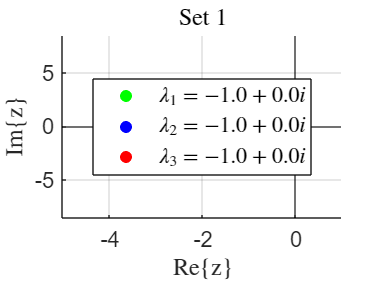

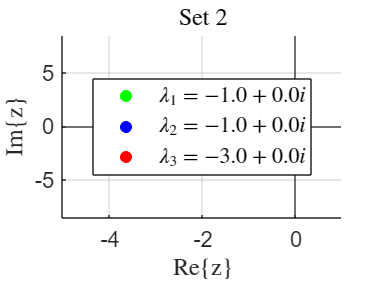

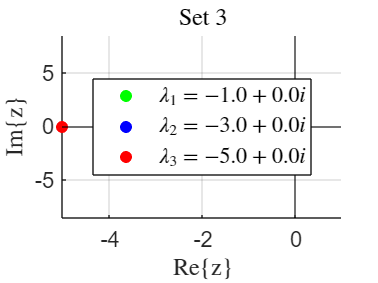

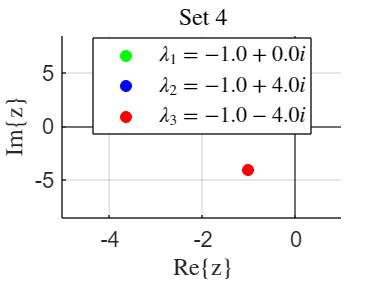

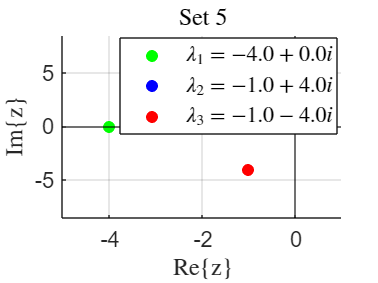

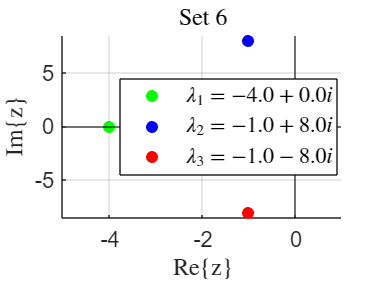

pole_sets = [
    [-1, -1, -1];
    [-1, -1, -3];
    [-1, -3, -5];
    [-1, -1+4i, -1-4i];
    [-4, -1+4i, -1-4i];
    [-4, -1+8i, -1-8i]
];


for i = 1:6
    current_poles = pole_sets(i,:);
    
    figure;
    xline(0, color="black", linestyle='-', LineWidth=0.5, HandleVisibility='off');
    hold on;
    yline(0, color="black", linestyle='-', LineWidth=0.5, HandleVisibility='off');
    hold on;
    pole_strs = arrayfun(@(p) sprintf('%.1f%+.1fi', real(p), imag(p)), current_poles, UniformOutput=false);
    p1 = plot(real(current_poles(1)), imag(current_poles(1)), 'g.', MarkerSize=20, ...
        DisplayName=sprintf('$\\lambda_{1}=%s$', pole_strs{1}));
    hold on;
    p2 = plot(real(current_poles(2)), imag(current_poles(2)), 'b.', MarkerSize=20, ...
        DisplayName=sprintf('$\\lambda_{2}=%s$', pole_strs{2}));
    hold on;
    p3 = plot(real(current_poles(3)), imag(current_poles(3)), 'r.', MarkerSize=20, ...
        DisplayName=sprintf('$\\lambda_{3}=%s$', pole_strs{3}));
  
    grid on;
    xlabel("Re\{z\}", Interpreter="latex");
    ylabel("Im\{z\}", Interpreter="latex");
    title(sprintf('Set %d', i), Interpreter="latex");
    legend(Location="best", FontSize=12, Interpreter="latex");
    set(gca, FontSize=12);

    xlim([-5, 1.0]);
    ylim([-8.5, 8.5]);
    hold off;
    
    filename = sprintf('images/poles_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200);
end

Set 1: Время переходного процесса = 6.296 с


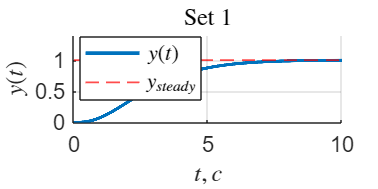

Set 2: Время переходного процесса = 5.130 с


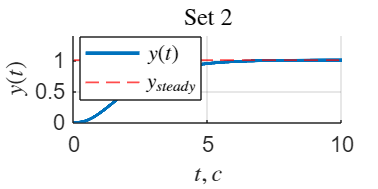

Set 3: Время переходного процесса = 3.624 с


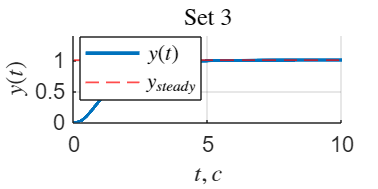

Set 4: Время переходного процесса = 2.781 с


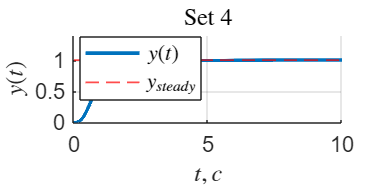

Set 5: Время переходного процесса = 2.739 с


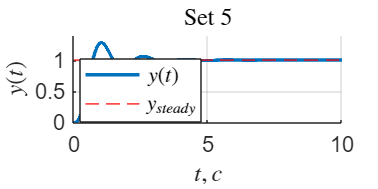

Set 6: Время переходного процесса = 2.176 с


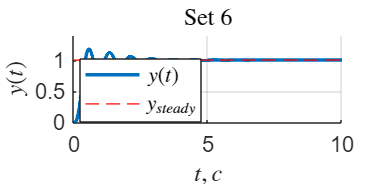


t = 0:0.001:10; 
u = ones(size(t));

for i = 1:6
    lambda_1 = pole_sets(i,1);
    lambda_2 = pole_sets(i,2);
    lambda_3 = pole_sets(i,3);

    W = zpk([], [lambda_1, lambda_2, lambda_3], abs(lambda_1*lambda_2*lambda_3));
    y = lsim(W, u, t);
    y_st = dcgain(W);

    delta = 0.05 * y_st;
    transition_time = NaN;
    
    for j = 1:length(t)
        if abs(y(j) - y_st) < delta
            if all(abs(y(j:end) - y_st) < delta)
                transition_time = t(j);
                break;
            end
        end
    end
    
    fprintf('Set %d: Время переходного процесса = %.3f с\n', i, transition_time);
    
    figure;
    yline(y_st, 'r--', 'LineWidth', 1, DisplayName="$y_{steady}$");
    hold on;
    plot(t, y, 'LineWidth', 2, 'LineStyle', '-', DisplayName="$y(t)$");
    grid on;
    ylabel("$y(t)$", Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    title(sprintf('Set %d', i), Interpreter="latex");
    legend(Location="best", FontSize=12, Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);
    set(gca, FontSize=12);
    ylim([0, 1.4]);
    filename = sprintf('images/per_proc_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200);
end


%Для перерeгулирования 
for i = 5:6
    lambda_1 = pole_sets(i,1);
    lambda_2 = pole_sets(i,2);
    lambda_3 = pole_sets(i,3);

    W = zpk([], [lambda_1, lambda_2, lambda_3], abs(lambda_1*lambda_2*lambda_3));
    y = lsim(W, u, t);
    y_st = dcgain(W);
    fprintf('Set %d: Перерегулирование = %.4f\n %', i, abs(max(y)-y_st)/y_st * 100);
end

Set 5: Перерегулирование = 27.7866
 Set 6: Перерегулирование = 17.5010
 